# Sample 12-1

## 画像復元

ウィーナーフィルタ

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Image restoraton

Wiener filter

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


## Read Pristine Image

Read and display a pristine image that does not have blur or noise.

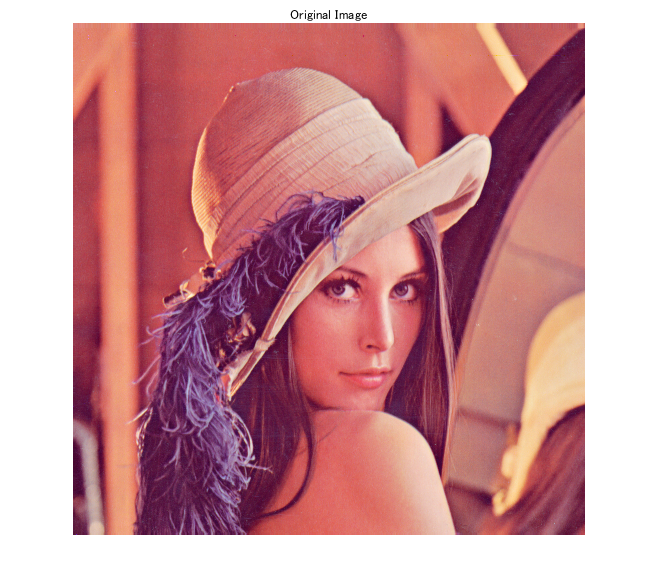

Ioriginal = imread('./data/lena.png');
imshow(Ioriginal)
title('Original Image')

## Simulate and Restore Motion Blur Without Noise

Simulate a blurred image that might result from camera motion. First, create a point-spread function, `PSF`, by using the [`fspecial`](docid:images_ref#f2-71998) function and specifying linear motion across 21 pixels at an angle of 11 degrees. Then, convolve the point-spread function with the image by using [`imfilter`](docid:images_ref#btsmcj2-1).

The original image has data type `uint8`. If you pass a `uint8` image to `imfilter`, then the function will quantize the output in order to return another `uint8` image. To reduce quantization errors, convert the image to `double` before calling `imfilter`.

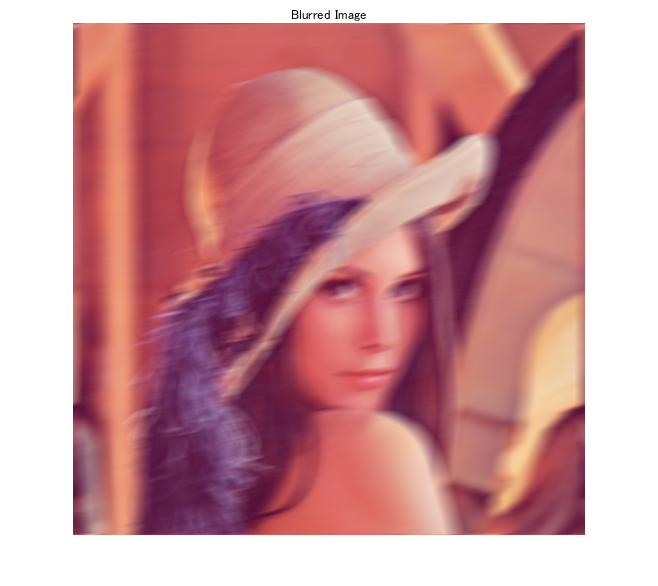

PSF = fspecial('motion',21,11);
Idouble = im2double(Ioriginal);
blurred = imfilter(Idouble,PSF,'conv','circular');
imshow(blurred)
title('Blurred Image')

Restore the blurred image by using the [`deconvwnr`](docid:images_ref#f1-288163) function. The blurred image does not have noise so you can omit the noise-to-signal (NSR) input argument.

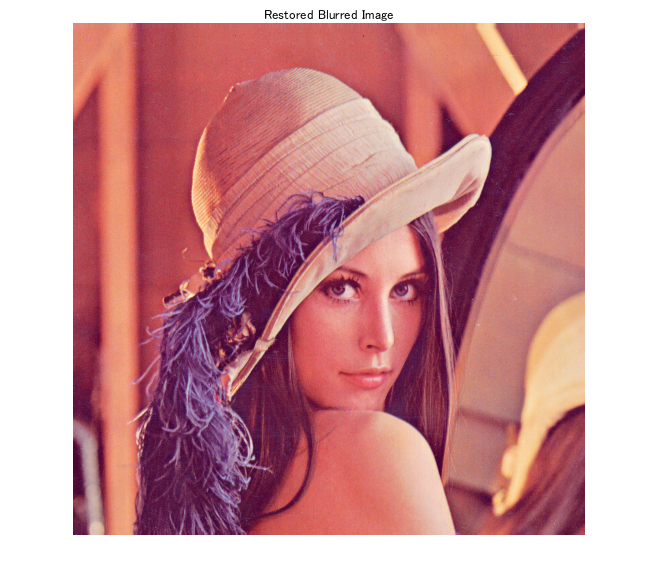

wnr1 = deconvwnr(blurred,PSF);
imshow(wnr1)
title('Restored Blurred Image')

## Simulate and Restore Motion Blur and Gaussian Noise

Add zero-mean Gaussian noise to the blurred image by using the [`imnoise`](docid:images_ref#f5-195189) function.

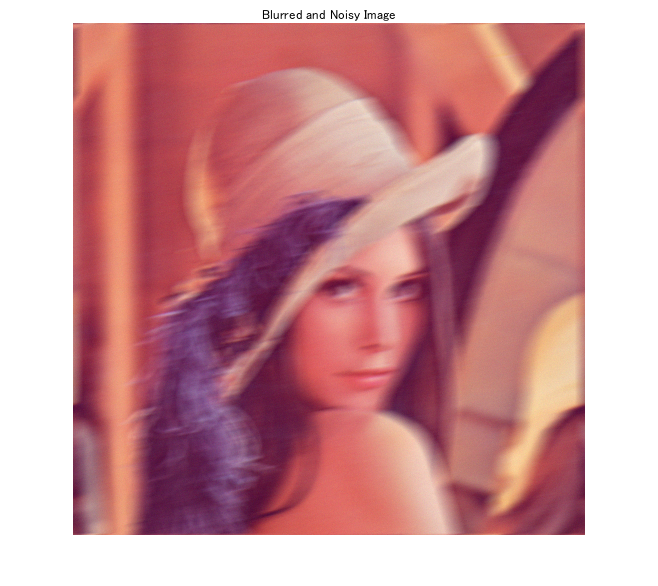

noise_mean = 0;
noise_var = 0.0001;
blurred_noisy = imnoise(blurred,'gaussian',noise_mean,noise_var);
imshow(blurred_noisy)
title('Blurred and Noisy Image')

Try to restore the blurred noisy image by using `deconvwnr` without providing a noise estimate. By default, the Wiener restoration filter assumes the NSR is equal to 0. In this case, the Wiener restoration filter is equivalent to an ideal inverse filter, which can be extremely sensitive to noise in the input image. 

In this example, the noise in this restoration is amplified to such a degree that the image content is lost.

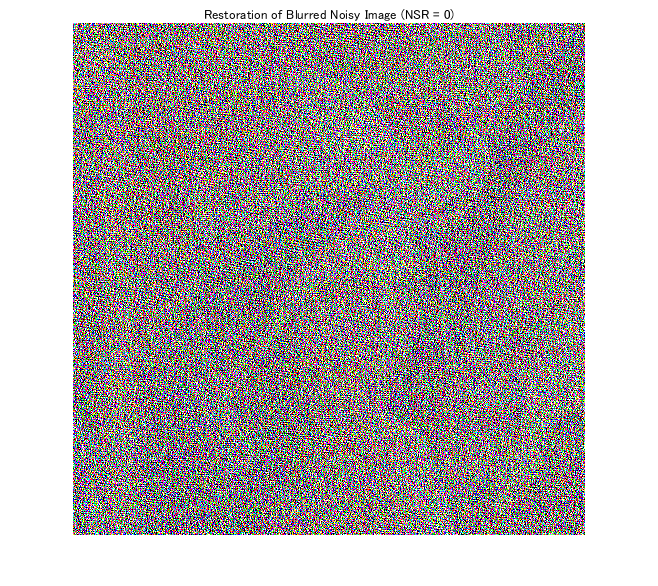

wnr2 = deconvwnr(blurred_noisy,PSF);
imshow(wnr2)
title('Restoration of Blurred Noisy Image (NSR = 0)')

Try to restore the blurred noisy image by using `deconvwnr` with a more realistic value of the estimated noise.

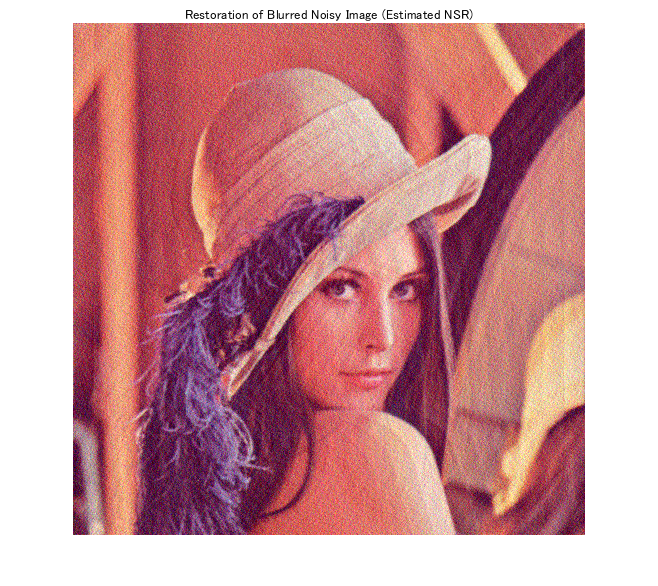

signal_var = var(Idouble(:));
NSR = noise_var / signal_var;
wnr3 = deconvwnr(blurred_noisy,PSF,NSR);
imshow(wnr3)
title('Restoration of Blurred Noisy Image (Estimated NSR)')

© Copyright, Shogo MURAMATSU, All rights reserved.